# **Series  de Fourier**

## **Asignatura de programacion en ingeniria  **

**Contexto**

Las ondas cuadradas son básicamente ondas que pasan de un estado a otro de tensión, a intervalos regulares, en un tiempo muy reducido. Son utilizadas usualmente para probar amplificadores (esto es debido a que este tipo de señales contienen en sí mismas todas las frecuencias). La televisión, la radio y los ordenadores utilizan mucho este tipo de señales, fundamentalmente como relojes y temporizadores.

Un ejemplo de onda cuadrada es la onda de corriente continua (DC), la cual alterna su valor entre dos intervalos extremos sin pasar por los valores intermedios (caso contrario de lo que sucede con la onda senoidal y la onda triangular).

La onda cuadrada se usa principalmente para la generación de pulsos eléctricos que son usados como señales (1 y 0). Un circuito electrónico que genera ondas cuadradas se conoce como generador de pulsos, este tipo de circuitos es la base de la electrónica digital y su manipulación no requiere de conocimientos avanzados.

**Labor**

Utilice la serie de Fourier para aproximar la siguiente función a trozos o por partes:

# 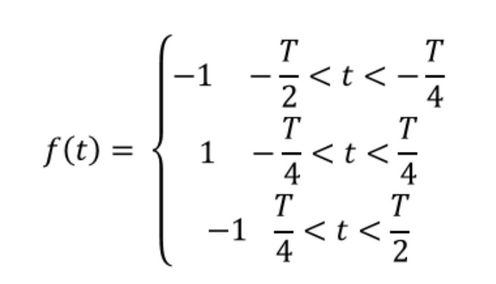

**Solucion **

**Parametros de la funcion **

clear all, clc
format short
a  = -3;          %Limite inferior del vector de tiempo
b  =  3;          %Limite superior del vector de tiempo
t  = a:0.01:b;    % Vector de tiempo 
nt = 3;           % Numero de intervalos
T  = 2*pi         % Periodo de la funcion 

T = 6.2832

w  = 2*pi/T       % Frecuencia angular 

w = 1

N  = 16           % Numero de terminos de la serie 

N = 16

Funcion a trozos 

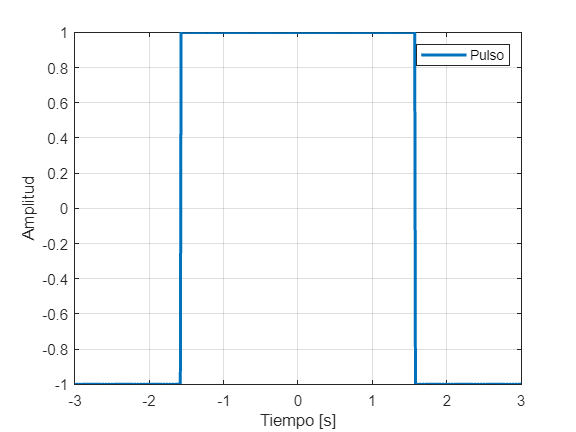

T1 = ((t>=(-T/2))&(t<(-T/4)));
T2 = ((t>(-T/4))&(t<(T/4)));
T3 = ((t>(T/4))&(t<(T)));
f1 = -1;
f2 =  1;
f3 = -1;
FTrozos(t,nt,T1,f1,T2,f2,T3,f3);

Coeficienes de Fourier 

format short
format shortE
syms t n 
a0 = (2/T)*(int(-1,t,-pi,(-pi./2)) + int(1,t,(-pi./2),(pi./2)) + int(-1,t,(pi./2),(pi)))

$$a0 = 0$$

an = (2/T)*(int(-cos(n.*w.*t),t,-pi,(-pi./2)) + int(cos(n.*w.*t),t,(-pi./2),(pi./2)) + int(-cos(n.*w.*t),t,(pi./2),(pi)))

$$an = \frac{5734161139222659\,\sin\left(\frac{\pi \,n}{2}\right)}{9007199254740992\,n}-\frac{5734161139222659\,\left(\sin\left(\pi \,n\right)-\sin\left(\frac{\pi \,n}{2}\right)\right)}{9007199254740992\,n}$$

bn = (2/T)*(int(-sin(n.*w.*t),t,-pi,(-pi./2)) + int(sin(n.*w.*t),t,(-pi./2),(pi./2)) + int(-sin(n.*w.*t),t,(pi./2),(pi)))

$$bn = 0$$

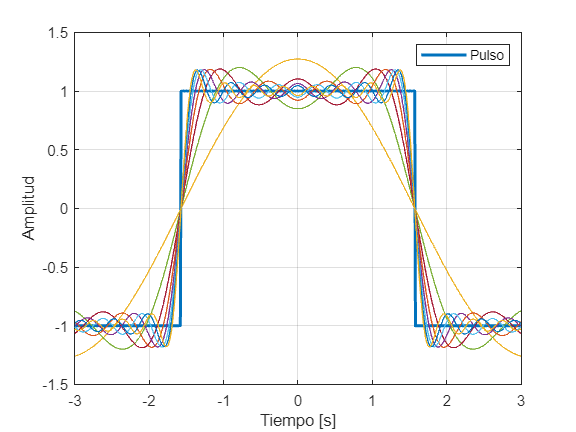

tiempo = [a:0.01:b];
sum= a0;
for nn=1:1:N;
    An = double(subs(an,n,nn));
    Bn = double(subs(bn,n,nn));
    sum=sum+An.*cos(nn.*tiempo)+Bn.*sin(nn.*tiempo);
    plot(tiempo,sum)
    legend('Pulso');
    xlabel('Tiempo [s]');
    ylabel('Amplitud');
    grid on
end

**Grafico de funcion a trozos  **

function Trozos = FTrozos(t,nt,T1,f1,T2,f2,T3,f3)
%t  : Venctor de tiempo
% nt: Numero de tramos de la funcion 
% T : Intervalo de la funcion 
% ft: Funcion definida en el intervalo 
%Variables de entrada 
%Tr : Intervalo 
%Ft : Funsion 
%Variables de salida
%Grafico de funcion a trozos
if nt == 2
    f=(((T1)).*(f1) + ((T2)).*(f2))
    plot(t,f, "LineWidth",2)
    legend('Pulso');
    xlabel('Tiempo [s]');
    ylabel('Amplitud');
    hold on 
    grid on 

end
if nt == 3
    f=(((T1)).*(f1) + ((T2)).*(f2) + ((T3)).*(f3));
    plot(t,f, "LineWidth",2)
    legend('Pulso');
    xlabel('Tiempo [s]');
    ylabel('Amplitud');
    hold on 
    grid on
end

end